# Problem 2: Aerobraking

Student 1: Álvaro Reviriego Moreno 

Student 2: Enrique Sentana Gómez

Data of the problem:

clear all;
mu = 42828.4;                       % mu Mars [km^3/s^2] 
RM = 3389.9;                        % Radius of Mars [km]

% Orbit parameters 
a = 5840;                           % Semi-major axis [km]
e = 0.4;                            % Eccentricity 
Omega = deg2rad(194);               % RAAN 
i = deg2rad(56);                    % Inclination 
omega = deg2rad(258);               % Argument of periapsis 
theta_0 = deg2rad(230);             % True anomaly at t=0 

% Spacecraft features
S = 10;                             % Shield area [m^2]
m = 3000;                           % Mass of the spacecraft [kg]
CD = 1.5;
% Reference values of the atmosphere at 120 km height 

T = 128;                            % Temperature [K]
R = 8.314;                          % Gas constant [J/K mol]
M = 43.4/1000;                      % Molar mass [kg/mol] 
zeta_ref = 120;                     % Reference height [km]
p_ref = 3.38e-4;                    % Pressure at zeta_ref (120km) [Pa]
g = 3.72;                           % Gravity [m/s^2]


## Initial position and velocity vectors

    The goal of this second problem related to aerobraking consists on analyzing the effect of the atmospheric drag on the evolution of the orbit of a determined body. In order to do the described task, the first step is to compute the initial state vector $X = [\vec{r},\vec{v}]$ from the given COEs. In order to do this, the function [`coe2stat.m`](matlab:open('./coe2stat.m')) is used. 

X_init = coe2stat([a,e,i,Omega,omega,theta_0],mu)       % Initial state vector 

X_init = 	1.0e+03 *

    4.6487
   -1.8398
    4.3140
    0.0009
    0.0014
   -0.0017


## Ideal 2BP Cowell propagation and convergence study

    This section is devoted to analyze the propagation returned from a numerical integrator for different values of $\delta t$. The values selected for the time-step are $\delta t = [300, 150, 75, 37.5] s$. The method used to calculate the propagation of the orbit 'Runge-Kutta $4^{th}$ order' (RK4) integrator. 

    Runge-Kutta methods are a set of implicit and explicit iterative methods of numerical resolution of ordinary differential ecuations (ODE). If we define an initial value problem (IVP)

 $y' = f(x,t)$, with $y(x_0) = y_0$

    The following RK4 steps are implemented by the following scheme,


$$y_{i+1} = y_{i} + \frac{1}{6}h(k_{1} + 2k_{2}+2k_{3}+k_{4})$$


    where $h $ is the time step and k are the intermediate coefficients, given by the following set of equations:


$$
k_{1} = f(x_{i},y_{i}) \\
k_{2} = f(x_{i}+ \frac{1}{2}h, y_{i}+ \frac{1}{2}hk_{1})\\
k_{3} = f(x_{i}+ \frac{1}{2}h, y_{i}+ \frac{1}{2}hk_{2}) \\
k_{4} = f(x_{i}+h, y_{i}+hk_{3})
$$


    As it can be seen above, in order to implement the RK4 method, the set of ODEs that governs the orbit of the body must be clearly defined. There are many ways to define the differential equations governing the propagation of the orbit, but in this task Cowell's formulation is used. Cowell's formulation consists on adding to the gravitational acceleration of the body (the one with no perturbation) the acceleration due to the atmospheric drag, which can be defined as: 


$$\vec{a_{P}} = -\frac{1}{2\cdot B_{c}} \cdot  \rho\cdot v\cdot \vec{v} = -\frac{1}{2} \frac{C_{D}S}{m_{P}} \cdot \rho\cdot v\cdot \vec{v}$$


    This acceleration due to the drag is calculated in the function [`drag_acceleration.m`](matlab:open('./drag_acceleration.m')). It must also be noted that the density of the atmosphere ($\rho$) is calculated in the function [`mars_atmosphere.m`](matlab:open('./Mars_atmosphere.m')). This function is developed to return the air density on Mars atmosphere at a certain height by knowing the atmospheric conditions at a reference height (in this case, reference height is 120 km). As a first step, atmospheric density at the reference height may be calculated with the known conditions: 


$$\rho_{ref} = \frac{P_{ref} \cdot M}{R\cdot T}$$


    Then, the scale height parameter is computed, considering an isothermal atmosphere and a negligible gradient in gravity acceleration. 


$$H = \frac{R \cdot T }{g\cdot M}$$


    Finally, one may use the scale height parameter in order to compute the air density anywhere, by means of the following relation with the reference density: 


$$\rho(\xi) = \rho_{ref} \cdot  exp(-\frac{\xi - \xi_{ref} }{H})$$


    With the expression for the air density, we can make use of the equation above to compute the perturbation acceleration. Once the perturbation acceleration is calculated, we can pose the Cowell's formulation of the 2-Body perturbed problem, implemented in the [`Cowell.m`](matlab:open('./Cowell.m')) function:


$$\frac{\mathrm{d^2} \vec{r}}{\mathrm{d} t^2} = - \frac{\mu}{r^3}\vec{r} + \vec{a_{P}}$$


    The mentioned [`Cowell.m`](matlab:open('./Cowell.m')) function is the one introduced in the RK4 integrator to propagate the orbit in time. Note that in the implemented function [`RK4.m`](matlab:open('./RK4.m')), we define a flag as input. This flag is set to true if we want to compute the perurbed orbit, and set to false if we do not want to, leading to $\vec{a_{P}} = 0$. The goal of this section consist on analyzing the orbit with no perturbations, so the flag is set to false. 

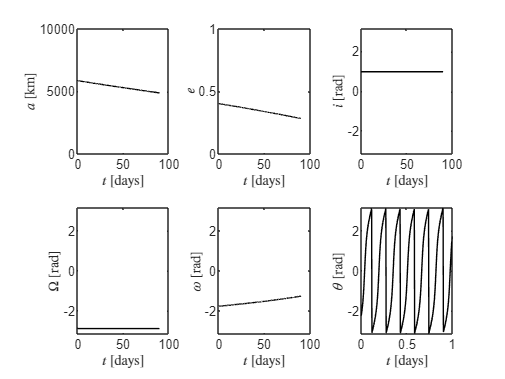

flag = false;
tf = 90*24*3600;

dt1 = 300;
t1 = 0:dt1:tf;
X1 = RK4(X_init,dt1,flag);

for j =1:length(X1)
    coe1(:,j) = stat2coe(X1(:,j),mu); 
end


figure(1)
plot_orbit(t1,coe1)

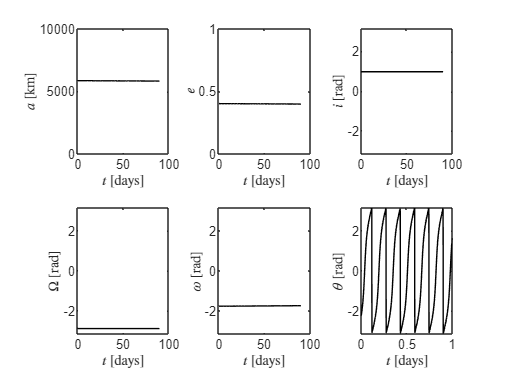


dt2 = 150; 
t2 = 0:dt2:tf;
X2 = RK4(X_init,dt2,flag);

for j =1:length(X2)
    coe2(:,j) = stat2coe(X2(:,j),mu); 
end

figure(2)
plot_orbit(t2,coe2)

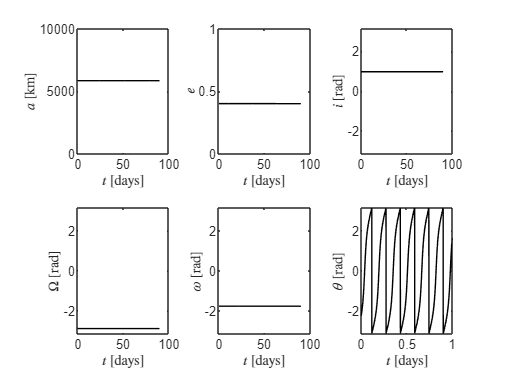


dt3 = 75;
t3 = 0:dt3:tf; 
X3 = RK4(X_init,dt3,flag);

for j =1:length(X3)
    coe3(:,j) = stat2coe(X3(:,j),mu); 
end

figure(3)
plot_orbit(t3,coe3)

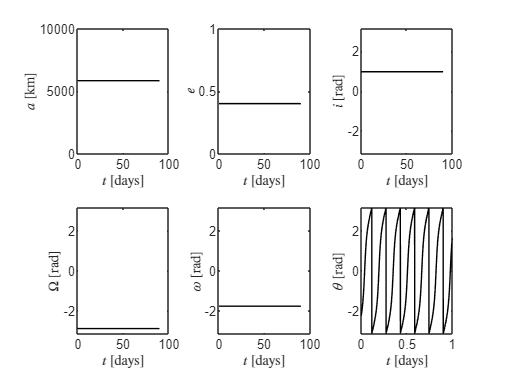


dt4 = 37.5;
t4 = 0:dt4:tf;
X4 = RK4(X_init,dt4,flag);

for j =1:length(X4)
    coe4(:,j) = stat2coe(X4(:,j),mu); 
end

figure(4)
plot_orbit(t4,coe4)

    As expected, the COEs remains constant (except the true anomaly which is cyclic) for an unperturbed orbit. Note that for the first time-step $\delta t_{1} = 300 s$, it can be seen that the orbit is slightly perturbed. However, this perturbation appears due to numerical errors in the implementation of the Runge-Kutta integrator. As seen in the other figures for smaller time steps, this numerical error is corrected.

## Perturbed 2BP Cowell propagation

    This section is devoted to analyze the propagation of the orbit under the effect of the perturbation due to drag acceleration. In this case, the formulation is the same as in the previous section, with the main difference that now $\vec{a_{P} \neq 0$, so the flag is set to true. Moreover, we must note that in this section the time step used is $\delta t_{4} = 37.5 s$.

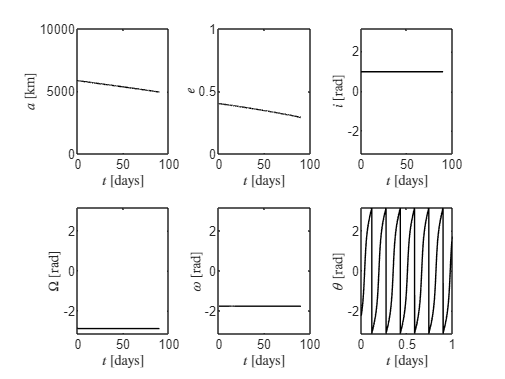

X4_2 = RK4(X_init,dt4,true);

for k=1:length(X4_2(1,:))
    coe4_2(:,k) = stat2coe(X4_2(:,k),mu);
end

figure(5)
plot_orbit(t4,coe4_2) 

    Results for a perturbed orbit are the expected ones: the semi-major axis is reducing as a direct consequence of the atmospheric drag, as well as the eccentricity tends to 0 (i.e. the orbit tends to a circular one). The rest of the COEs remains as in the unperturbed case since the atmospheric drag perturbation does not produce any out-of-plane perturbation. 

## Time to reentry

    In this final section, we need to consider that the spacecraft is in a circular orbit over Mars. As shown above, this orbit is perturbed and its radius is constantly reducing in time due to the atmospheric drag effect. In this particular case, a circular orbit at 150km height over Mars is considered with $a = R_M + h $ and $e = 0 $ (the rest of the COEs are considered to be the same as before, for simplicity) 

a_r = RM + 150; 
e_r = 0; 
i_r = deg2rad(56); 
Omega_r = deg2rad(194);
omega_r = deg2rad(258);
theta_r = deg2rad(230); 

    Initially, we can compute analytically the time until reaching Mars surface by applying the following relation derived from the integration of the vis-viva equation, which allow us to compute the time between two different heights just by knowing the density of the air at both points. In this case, the twoo densities ($\rho_{1}$ at 150 km height and $\rho_{2}$ at Mars surface) are computed by making use again of the [mars_atmosphere.m](matlab:open('./Mars_atmosphere.m')) function. 


$$\Delta t = \frac{H  B_c}{\sqrt{\mu a}}(\frac{1}{\rho_{1}} -\frac{1}{\rho_{2}})$$
 

H = R*T/(g*M);                  % Scale-height parameter 
BC = m/(CD*S);                  % Ballistic coefficient [kg/m^2]
rho_1 = Mars_atmosphere(150);   % Density at 150 km height [kg/m^3]
rho_2 = Mars_atmosphere(0);     % Density at Mars surface [kg/m^3]

delta_t = (H*BC)/sqrt(mu*1000^3*a_r*1000) * (1/(rho_1) - 1/(rho_2)); 
disp(delta_t/(24*3600))

    8.5183



    The result give us a flight time of 8.52 days until spacecraft reaches Mars atmosphere. Furthermore, we can compare this result with the numerical one. The procedure to follow is pretty similar as before: compute the evolution of the orbit by numerical integration using the [RK4.m](matlab:open('./RK4.m')) function.  

    Once the COEs are selected, we may find the initial state vector and integrate it numerically in order to see the evolution of the orbit parameters in time

X_init_r = coe2stat([a_r,e_r,i_r,Omega_r,omega_r,theta_r],mu);
dt_r = 37.5; 
t_r = 0:dt_r:tf;

X_r = RK4(X_init_r,dt_r,true); 
for k=1:length(X_r(1,:))
    coe_r(:,k) = stat2coe(X_r(:,k),mu);
end

    We are interested at the moment where the contact of the body with Mars surface is produced, which happens when $a = 0$. Hence we can plot the evolution of height ($h = a - R_M$) with time to see when it crosses the zero line.

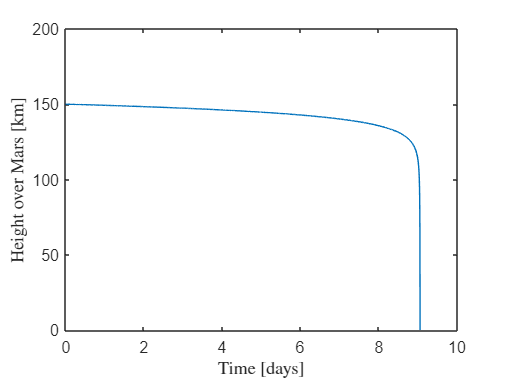

figure(6)
plot(t_r/(24*3600), coe_r(1,:)-RM)
ylabel('Height over Mars [km]', 'Interpreter','latex')
xlabel('Time [days]','Interpreter','latex')
ylim([0,200])

    The result obtained is that the body will crash into Mars surface after approximately 9 days, which is approximately the same as the analytical one. However, as we know, there are some errors associated to the numerical integration, specially when the height over the Mars surface is lower than 50 km  ($\xi < 50$km). Furthermore, some limitations can be found in the analytical result due to errors in the isothermal atmospheric model close to Mars surface used to compute the air density. 